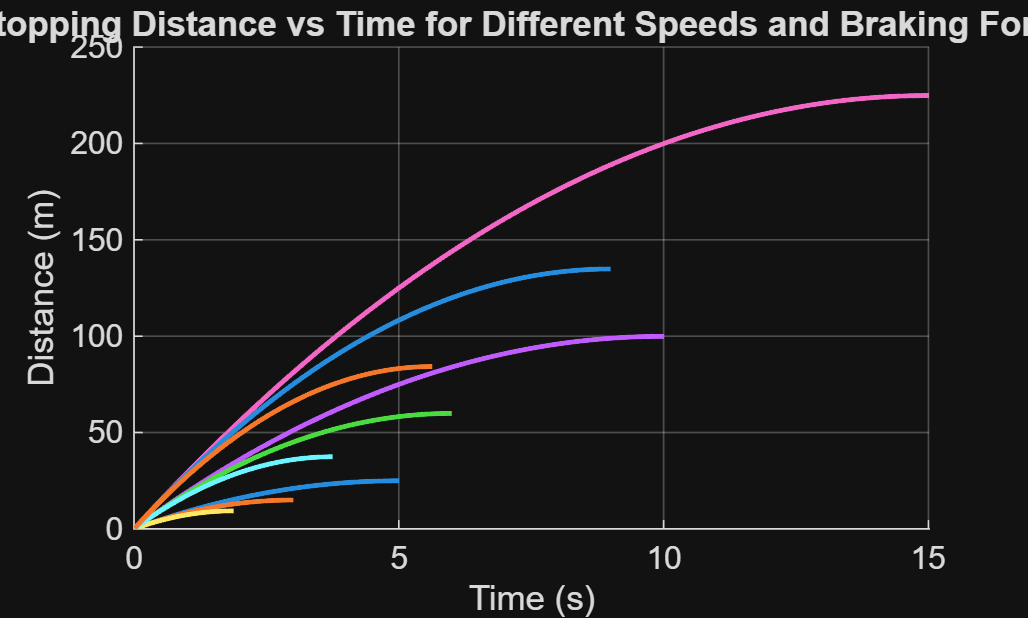

% Parameters
m = 1500;                 % mass (kg)
Fb_values = [3000 5000 8000];   % braking forces (N)
v0_values = [10 20 30];   % initial speeds (m/s)

dt = 0.01;                % time step
colors = lines(length(v0_values));

figure;
hold on;

for i = 1:length(v0_values)
    v0 = v0_values(i);

    for j = 1:length(Fb_values)
        Fb = Fb_values(j);
        a = -Fb/m;

        v = v0;
        x = 0;
        t = 0;

        x_vals = [];
        t_vals = [];

        % Time-stepping loop
        while v > 0
            v = v + a*dt;
            if v < 0
                v = 0;
            end
            x = x + v*dt;

            t = t + dt;

            x_vals(end+1) = x;
            t_vals(end+1) = t;
        end

        plot(t_vals, x_vals, 'LineWidth', 1.5);
        
        % Store stopping distance
        stopping_distance(i,j) = x;
    end
end

xlabel('Time (s)');
ylabel('Distance (m)');
title('Stopping Distance vs Time for Different Speeds and Braking Forces');
grid on;